# Løsning til eksamenssæt 2021E

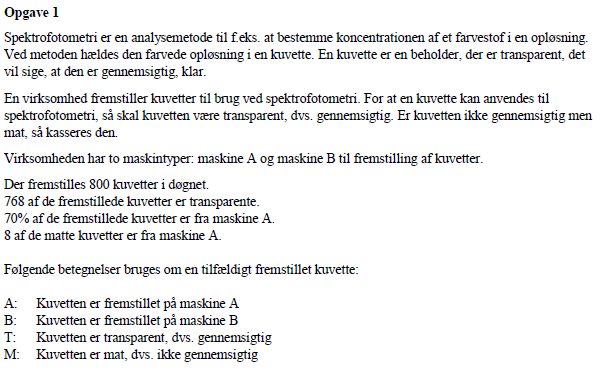

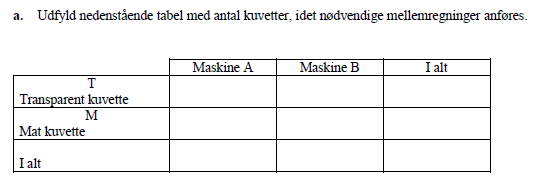

clc; clear

n = 800 % total

n = 800


nT = 768

nT = 768

nM = n-nT

nM = 32


nA = 0.7*n

nA = 560

nB = n-nA

nB = 240


Amat = 8

Amat = 8

Bmat = nM - Amat

Bmat = 24


Atrans = nA - Amat

Atrans = 552

Btrans = nB - Bmat

Btrans = 216



rownames = ["Transparent";"Mat";"I alt"];
varnames = ["Maskine A","Maskine B","I alt"]

varnames = 1×3 string array
    "Maskine A"    "Maskine B"    "I alt"



disp(table([Atrans;Amat;nA],[Btrans;Bmat;nB], [Atrans+Btrans;Bmat+Amat;n],RowNames=rownames,VariableNames=varnames))

                   Maskine A    Maskine B    I alt
                   _________    _________    _____

    Transparent       552          216        768 
    Mat                 8           24         32 
    I alt             560          240        800 



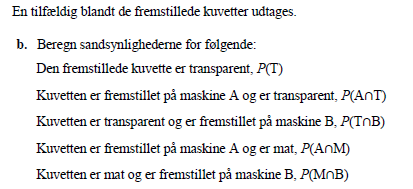

P_T = nT/n

P_T = 0.9600

P_A_og_T = Atrans/n

P_A_og_T = 0.6900

P_T_og_B = Btrans/n

P_T_og_B = 0.2700

P_A_og_M = Amat/n

P_A_og_M = 0.0100

P_M_og_B = Bmat/n

P_M_og_B = 0.0300

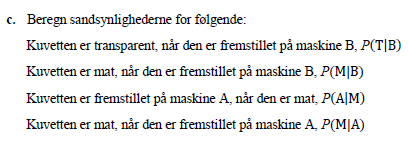

P_T_givet_B = Btrans/nB

P_T_givet_B = 0.9000

P_M_givet_B = Bmat/nB   % 1 - P_T_givet_B

P_M_givet_B = 0.1000

P_A_givet_M = Amat/(Amat+Bmat)

P_A_givet_M = 0.2500

P_M_givet_A = Amat/nA

P_M_givet_A = 0.0143

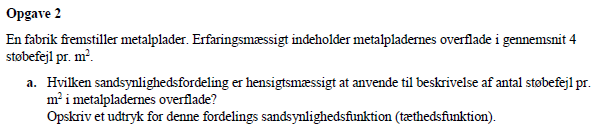

Der kan bruges en poisson fordeling, eftersom man kender for forventede antal støbefejl, pr enhed

clc; clear;

lambda = 4;

mu = lambda

mu = 4

varians = lambda

varians = 4

stdafv = sqrt(lambda)

stdafv = 2

P_3_fejl = poisspdf(3,lambda)

P_3_fejl = 0.1954

P_lig_eller_mindre_end_6_fejl = poisscdf(6,lambda)

P_lig_eller_mindre_end_6_fejl = 0.8893

P_lig_eller_storre_end_7_fejl = 1 - poisscdf(6,lambda)

P_lig_eller_storre_end_7_fejl = 0.1107

% 5 ikke inkluderet
P_mellem_2_og_5_fejl = 1 - poisscdf(2,lambda) - (1 - poisscdf(4,lambda))

P_mellem_2_og_5_fejl = 0.3907


% 5 inkluderet
P_mellem_2_og_5_fejl = 1 - poisscdf(2,lambda) - (1 - poisscdf(5,lambda))

P_mellem_2_og_5_fejl = 0.5470

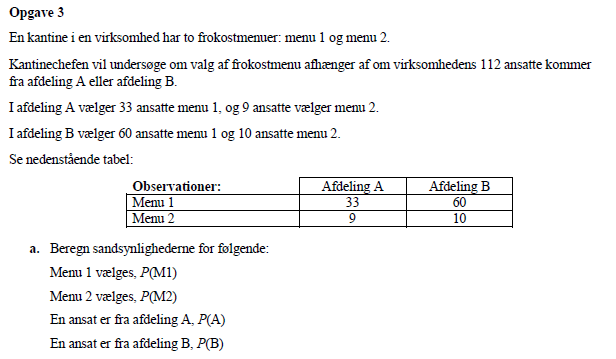

clc; clear;

n = 112

n = 112


nA = 42

nA = 42

nB = 70

nB = 70


Amenu1 = 33

Amenu1 = 33

Amenu2 = 9

Amenu2 = 9


Bmenu1 = 60

Bmenu1 = 60

Bmenu2 = 10

Bmenu2 = 10



P_menu_1 = (Amenu1 + Bmenu1)/n

P_menu_1 = 0.8304

P_menu_2 = (Amenu2 + Bmenu2)/n

P_menu_2 = 0.1696


P_afdeling_A = nA/n

P_afdeling_A = 0.3750

P_afdeling_B = nB/n

P_afdeling_B = 0.6250

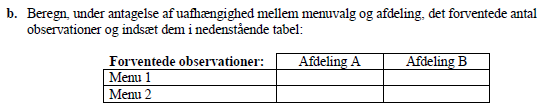

KT = KontingensTabel([33,60;9,10]);

        Data navn         Maskine A | Maskine B | Maskine C
    __________________    _________________________________

    "Intakt forventet"            34.875    58.125         
    "Defekt forventet"             7.125    11.875         




% Og afrundet
round(KT,0)

ans =     35    58
     7    12


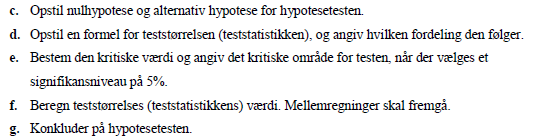

H0: Valg af menu er uafhængig

Ha: Valg af menu er ikke uafhængig

Formel for teststørrelsen


$${\chi_{0}}^{2}={\Sigma_{i}}^{k}\,{\Sigma_{j}}^{k}\,\frac{{\left(O_{\mathrm{ij}}-E_{\mathrm{ij}}\right)}^{2}}{E_{\mathrm{ij}}}$$

-----------------------------------------------------------------
Antal frihedsgrader


$$\mathrm{dfs}=\left(r-1\right)\,\left(c-1\right)$$

-----------------------------------------------------------------
Kritiske grænse - MATLAB kommando


$${\chi_{\alpha }}^{2}=\mathrm{chi2inv}\,\alpha \,\mathrm{dfs}$$

-----------------------------------------------------------------
    Signifikansniveau    Frihedsgrader    Kritisk grænse    Teststørrelse
    _________________    _____________    ______________    _____________

          "%5"                 1              3.8415           0.95076   



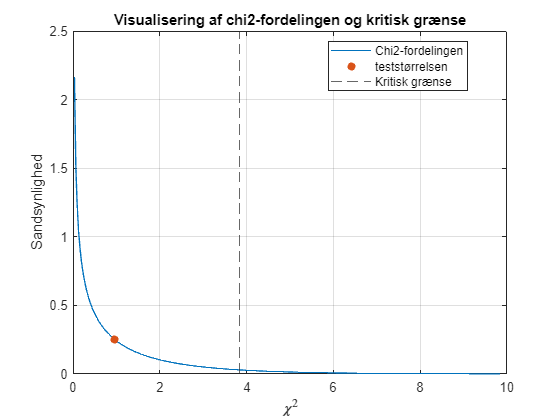

chi2normal_Test_8_uafh([33,60;9,10],[KT(1,:); KT(2,:)],95)

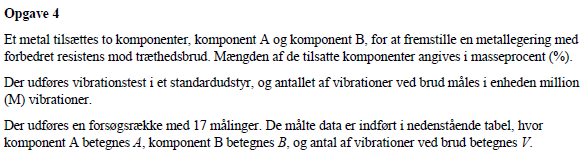

clc; clear;

data = importdata("Data_M4STI1_2021E.xlsx");
data = data.data(:, 5:end)

data =     4.5000   10.0000   21.1000
    4.5000    8.0000   18.5000
    4.5000    9.0000   19.2000
    4.5000    9.0000   21.4000
    5.5000    8.0000   22.3000
    5.5000    9.0000   25.1000
    5.5000    9.0000   24.8000
    5.5000    9.0000   24.9000
    5.5000    9.0000   25.1000
    5.5000    8.0000   21.2000


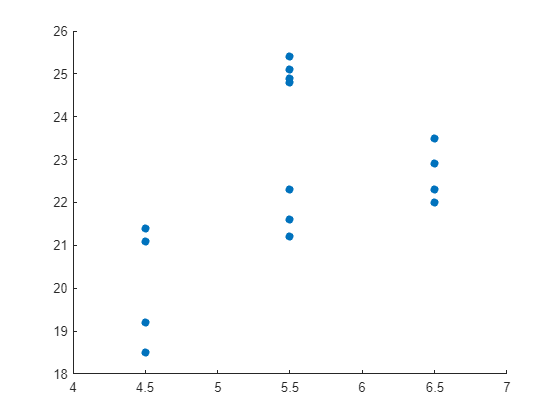



figure
scatter(data(:,1),data(:,3), "filled")
xlim([4,7])

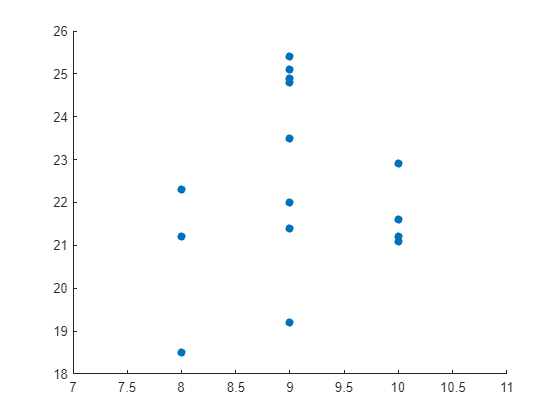


figure
scatter(data(:,2),data(:,3),"filled")
xlim([7,11])

mdl = fitlm(data(:,1:2), data(:,3))

mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE       tStat      pValue 
                   ________    _______    ______    ________

    (Intercept)     12.469        7.35    1.6964     0.11192
    x1              1.3125     0.69538    1.8875    0.080004
    x2              0.3125     0.69538    0.4494     0.66002


Number of observations: 17, Error degrees of freedom: 14
Root Mean Squared Error: 1.97
R-squared: 0.212,  Adjusted R-Squared: 0.0993
F-statistic vs. constant model: 1.88, p-value = 0.189

Ud fra modellen bliver regressionsligningen

V = 12,469 + 1.3125A + 0.3125B

Lav R-værdi

Ingen af koefficienterne kan siges at være forskellig fra 0, eftersom alle p-værdier er større end 0.05

ydermere er F-statistikkens p-værdi også større end 0.05, og H0 siger at data er ukorrelerede, som ikke kan forkastes, hvilket betyder at b1 og b2 begge kan være 0 på samme tid

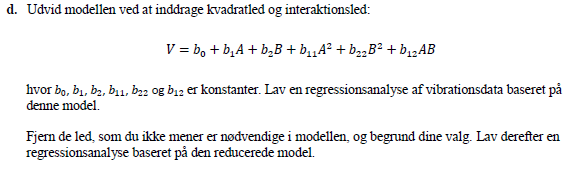

mdl2 = fitlm(data(:,1:2), data(:,3),'y ~ x1 + x2 + x1^2 + x2^2 + x1:x2')

mdl2 = Linear regression model:
    y ~ 1 + x1*x2 + x1^2 + x2^2

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)    -233.08      59.593    -3.9112    0.0024292
    x1              28.232      8.6834     3.2513    0.0077177
    x2              38.849      11.394     3.4096    0.0058295
    x1:x2             -0.5     0.62004    -0.8064       0.4371
    x1^2           -2.0382      0.6035    -3.3772    0.0061728
    x2^2           -1.9882      0.6035    -3.2944     0.007149


Number of observations: 17, Error degrees of freedom: 11
Root Mean Squared Error: 1.24
R-squared: 0.754,  Adjusted R-Squared: 0.642
F-statistic vs. constant model: 6.


% her er kun 1 koefficient ikke signifikant forskellig fra 0, så den
% fjernes (x1:x2)


mdl3 = fitlm(data(:,1:2), data(:,3),'y ~ x1 + x2 + x1^2 + x2^2')

mdl3 = Linear regression model:
    y ~ 1 + x1 + x2 + x1^2 + x2^2

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)    -208.33      50.332    -4.1392    0.0013729
    x1              23.732      6.5553     3.6203    0.0035126
    x2              36.099      10.712     3.3699    0.0055711
    x1^2           -2.0382     0.59464    -3.4275    0.0050083
    x2^2           -1.9882     0.59464    -3.3435    0.0058506


Number of observations: 17, Error degrees of freedom: 12
Root Mean Squared Error: 1.22
R-squared: 0.739,  Adjusted R-Squared: 0.652
F-statistic vs. constant model: 8.51, p-value = 0.00171



% Model 3 vælges over model 2, eftersom den ikke har koefficienter
% signifikant forskellig fra 0, dog med en lavere R^2 værdi, men bedre
% R^2-justeret værdi.


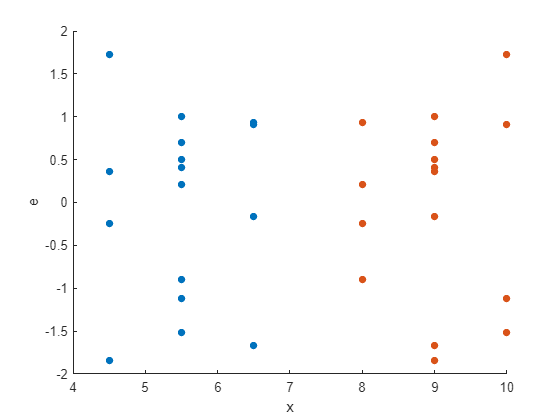

res = struct with fields:
         data: [17×9 table]
            k: 2
            n: 17
    lev_limit: 0.3529
    rst_limit: 3


res = STAT.Residual(mdl3,data)

res.lev_limit

ans = 0.3529